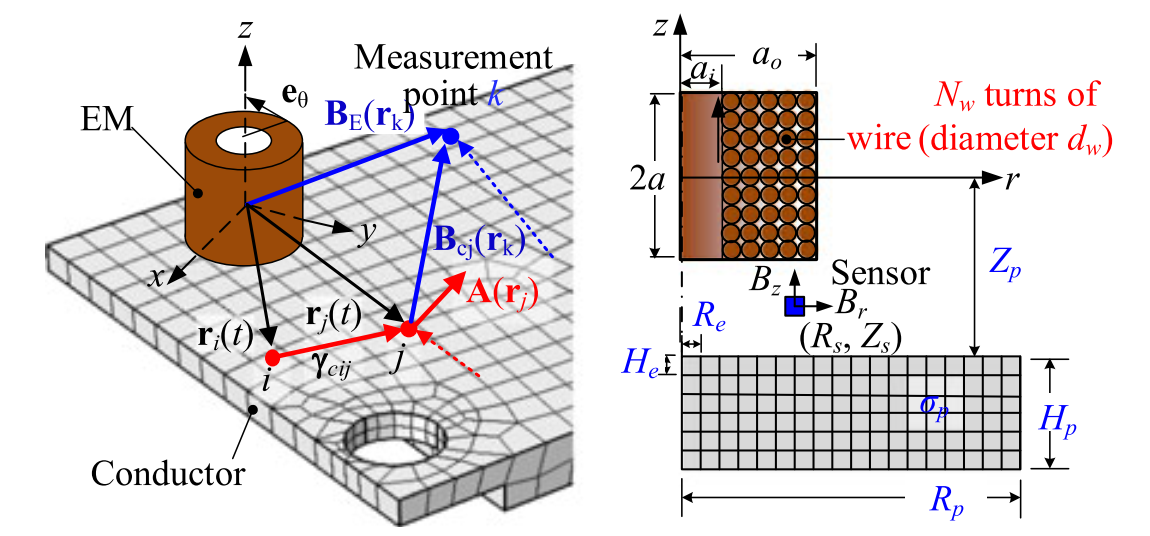

## Governing Equation

123

## Boundary Condition 

123                          

### Outputs

(n = Model.num_elms)

**GE.S**                  n-by-n matrix

**GE.Gamma_c**   n-by-n matrix

**GE.V**                  n-by-n matrix

**GE.Gamma_Ex** 1-by-n matrix

**GE.Gamma_Ey** 1-by-n matrix

**GE.Gamma_Ez** 1-by-n matrix

function GE = BuildGoveringEquation(EM, Model)

mu_0 = 4*pi*1e-7; % (H/m)

GE.S = mu_0 * diag(Model.conductivity);
GE.V = diag(Model.elms_volume);
GE.Gamma_c = Gamma_c_func(Model);
[GE.Gamma_Ex, GE.Gamma_Ey, GE.Gamma_Ez] = Gamma_E_func(Model, EM);

end

function Gamma_c = Gamma_c_func(Model)
    
n = Model.num_elms;
r_b = (3/(4*pi) * Model.elms_volume) .^ (1/3);

Gamma_c = zeros(n,n);

% off diagonal entries
for i = 1:n
    for j = i+1:n
        Gamma_c(i,j) = 1 / norm(Model.elms_center(:,j) - Model.elms_center(:,i));
    end
end
Gamma_c = Gamma_c + Gamma_c';

% diagonal entries
for i = 1:n
    Gamma_c(i,i) = 1.5 / r_b(:,i);
end

Gamma_c = Gamma_c / (4*pi);

end

function [Gamma_Ex, Gamma_Ey, Gamma_Ez] = Gamma_E_func(Model, EM)

Gamma_Ex = zeros(1, Model.num_elms);
Gamma_Ey = zeros(1, Model.num_elms);
Gamma_Ez = zeros(1, Model.num_elms);

for k = 1:EM.num
    H_w2l = EM.H_w2l(:,:,k);
    R_l2w = EM.R_l2w(:,:,k);
    ai = EM.ai(:,k);
    ao = EM.ao(:,k);
    l = EM.l(:,k);

    elms_center_w = Model.elms_center;
    [elms_center_l_x, elms_center_l_y, elms_center_l_z] = HomogenousTransform(H_w2l, elms_center_w(1,:), elms_center_w(2,:), elms_center_w(3,:));
    elms_center_l = [elms_center_l_x; elms_center_l_y; elms_center_l_z]; % 3-by-num_elms matrix

    Gamma_E_l_x = zeros(1, Model.num_elms);
    Gamma_E_l_y = zeros(1, Model.num_elms);
    Gamma_E_l_z = zeros(1, Model.num_elms);
    for i = 1:Model.num_elms
        Gamma_E_l_x(:,i) = integral3( ...
            @(r,z,theta)Gamma_E_Integrand(r,z,theta,elms_center_l(:,i)) .* -sin(theta), ...
            ai,ao,   -l/2,l/2,   0,2*pi                                     );

        Gamma_E_l_y(:,i) = integral3( ...
            @(r,z,theta)Gamma_E_Integrand(r,z,theta,elms_center_l(:,i)) .* cos(theta), ...
            ai,ao,   -l/2,l/2,   0,2*pi                                     );
    end

    [Gamma_E_w_x, Gamma_E_w_y, Gamma_E_w_z] = HomogenousTransform(R_l2w, Gamma_E_l_x, Gamma_E_l_y, Gamma_E_l_z);

    Gamma_Ex = Gamma_Ex + Gamma_E_w_x;
    Gamma_Ey = Gamma_Ey + Gamma_E_w_y;
    Gamma_Ez = Gamma_Ez + Gamma_E_w_z;
end

end

function value = Gamma_E_Integrand(r, z, theta, elm_center)
    dx = elm_center(1,1) - r .* cos(theta);
    dy = elm_center(2,1) - r .* sin(theta);
    dz = elm_center(3,1) - z;
    value = sqrt(dx.^2 + dy.^2 + dz.^2) .* r / (4*pi);
end